# Taller VI

### 02/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 3 y 4*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de interpolación polinomial*

`    [C, D] = newpoly (X, Y), `Polinomio de Newton

            - X es un vector que contiene la lista de abscisas

            - Y es un vector que contiene la lista de ordenadas

            - C es un vector que contiene los coeficientes del

                polinomio interpolante de Newton

            - D es la tabla de diferencias divididas

`    [C, L] = lagran (X, Y), `Polinomio de Lagrange

            - X es un vector que contiene una lista de las abscisas

            - Y es un vector que contiene una lista de las ordenadas

            - C es una matriz que contiene los coeficientes del

                polinomio interpolante de Lagrange

            - L es una matriz que contiene los coeficientes de los

                polinomios de Lagrange

`    [C, X, Y] = cheby (fun, n, a, b), `Nodos & Generador de Chebyshev

            - fun es la funcion introducida con @

            - N es el grado del polinomial interpolante de Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - C es la lista de coeficientes para el polinomio

            - X contiene las abscisas

            - Y contiene las ordenadas

`    [X, Y] = nodoschebyshev (fun, n, a, b), `Nodos de Chebyshev

            - fun es la funcion introducida con @

            - N es el grado del polinomial interpolante de Chebyshev

            - a es el extremo izquierdo

            - b es el extremo derecho

            - X contiene las abscisas

            - Y contiene las ordenadas

#### *        Métodos de interpolación por minimos cuadrados*

`    C = lspoly (X, Y, M), `Polinomio de minimos cuadrados

             - X es el vector de abscisas   1 x n

            - Y es el vector de ordenadas  1 x n

            - M es el grado del polinomio por minimos cuadrados

            - C es la lista de coeficientes para el polinomio

`    [A, B] = lsline (X, Y), `Linea de minimos cuadrados

            - X es el vector de abscisas   1 x n

            - Y es el vector de ordenadas  1 x n

            - A es el coeficiente de  x  en  Ax + B

            - B es el coeficiente constante en  Ax + B

#### *        Errores asociados*

        `Errores asociados a la aproximación de polinomios de Newton y Lagrange`

 
$$|E\left(x\right)|\le \;\frac{f^{\left(n+1\right)} \left(x^* \right)}{\left(n+1\right)!}\;\prod_{i=0}^n \left(x-x_i \right)$$


        `Errores asociados a la aproximación de polinomios con nodos de Cheby dentro del intervalo estandard `$I=\;\left\lbrack -1,1\right\rbrack$


$$|E\left(x\right)|\le \frac{1}{2^n \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


        `Errores asociados a la aproximación de polinomios con nodos de Cheby dentro del intervalo estandard `$I=\;\left\lbrack a,b\right\rbrack$


$$|E\left(x\right)|\le \frac{2\;{\left(b-a\right)}^{n+1} }{4^{n+1} \;\left(n+1\right)!}\;\max \left\lbrace f^{\left(n+1\right)} \left(\xi \left(x\right)\right)\right\rbrace$$


        `Errores asociados a la aproximación de funciones usando el métodos de minimos cuadrados`


$$|E\left(x\right)|=\sum_{i=0}^n |\;p\left(x_i \right)\;\;-\;f\left(x_i \right)|^2$$


***Nota:**** este método es equivalente al métodod de *`lsline0`

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

`Tabla de cambios de variable, para modelos`

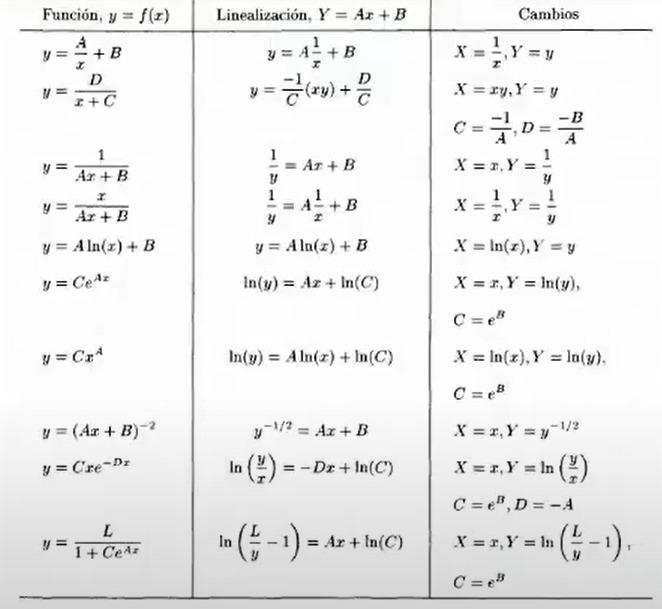

Para esta primera sesión se realiza el review que pueden encontrar en el drive

#### Interpolación

Para el taller de esta semana se solucionan los ejercicios $1,3$ del taller 6, se propone el uso de Newton y Lagrage, y las propias herramientas de Matlab

**8) **La rata de crecimiento de una colonia de bacterias es desconocida pero se tienen los siguientes datos: 

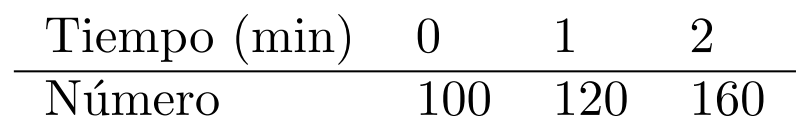

Establezca un ajuste exponencial de la forma $y=c\;e^{a\;x}$ para estos datos. Según este ajuste, ¿Cuál será la población a los 4 minutos?


$$y=c\;e^{a\;x} \to \log \left(y\right)=\log \left(c\right)+a\;x$$


clear 

X = 0:2; % Defino los nodos de X
Y = [100 120 160]; % Defino los valores de Y

[A, b] = lsline(X, log(Y)); % Hallo la interpolación Lineal
A, exp(b) % Valores de A y b.
F = @(x) exp(b) * exp(A*x); % Aproximamos el modelo
F(4) % Evaluamos en x = 4

**12) **Se propone el ejercicio del libro:

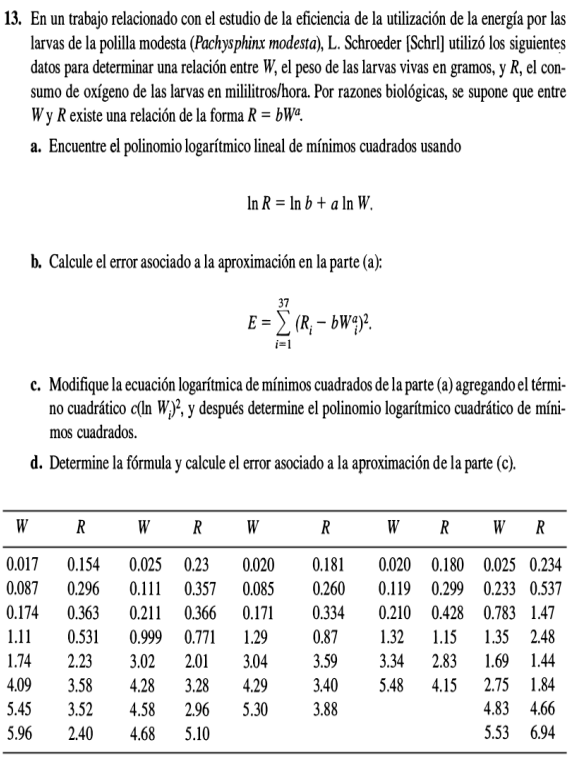

De la imagen se obtienen las siguientes ideas

- Datos propuestos para el analisis:

clear
W = [.017 .087 .174 1.11 1.74 4.09 5.45 5.96 ...
    .025 .111 .211 .999 3.02 4.28 4.58 4.68 ...
    .02 .085 .171 1.29 3.04 4.29 5.30 ...
    .02 .119 .210 1.32 3.34 5.48 ...
    .025 .233 .783 1.35 1.69 2.75 4.83 5.53]; % Valores de W


A = 0.2350

ans = 98.2593

R = [.154 .296 .363 .531 2.23 3.58 3.52 2.4 ...
    .23 .357 .366 .771 2.01 3.28 2.96 5.1 ...

ans = 251.5439

    .181 .26 .334 .87 3.59 3.40 3.88 ...
    .18 .299 .428 1.15 2.83 4.15 ...
    .234 .537 1.47 2.48 1.44 1.84 4.66 6.94]; % Valores de R

**a) **Encuentre el polinomio logaritmico lineal usando el método de minimos cuadrados:

[A, b] = lsline(log(W), log(R)); % Hallamos los valores de linealización
A, exp(b) % Valores de A y b.


$$R=e^{b+A\;\log \left(W\right)} \to R=e^b \;W^A$$


Cons = @(w) exp(polyval([A, b], log(w))); % Evaluo el modelo

**b) **Calcule el error asociado a la aproximación en la parte (a):


$$|x|=\sqrt{x_1^2 +\ldotp \ldotp \ldotp +{x_n }^2 }$$


E = R - Cons(W); % Hallamos el vector error
norm(E)^2 % Evaluamos el error cuadrado

A = 0.5756

ans = 1.3030

clf('reset')
hold on
fplot(Cons, [0, 6])
plot(W, R, '.r')
grid on
hold off

ans = 25.3018

**c) **Modifique el polinomio logaritmico lineal hallado en (a) agregando el termino cuadratico $c\;{\left(\ln \left(W_i \right)\right)}^2$, y determine este nuevo polinomio usando el método de minimos cuadrados:


$$\log \left(R\right)=\log \left(b\right)+a\;\log \left(W\right)+c\;{\left(\log \left(W\right)\right)}^2$$


C = lspoly(log(W), log(R), 2) % Hallamos la interpolación minimos cuadrados

**d) **Calcule el error asociado a la aproximación en la parte (c):

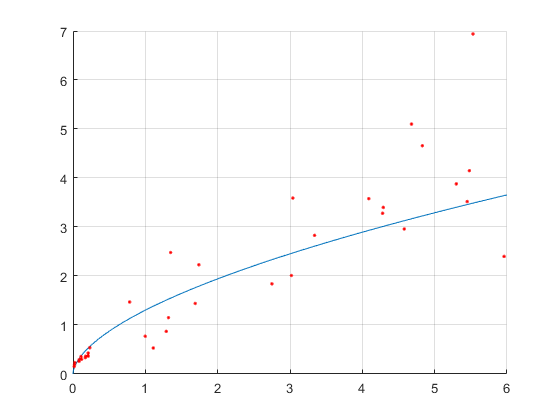

Cons = @(x) exp(polyval(C, log(x))); % Evaluamos el modelo
E = R - Cons(W); % Hallamos vector error
norm(E)^2 % Hallamos el error cuadrado
clf('reset')
hold on

fplot(Cons, [0, 6])
plot(W, R, '.r')
grid on

C =     0.0670
    0.7006
    0.0496


hold off

#### Preguntas realizadas durante el taller

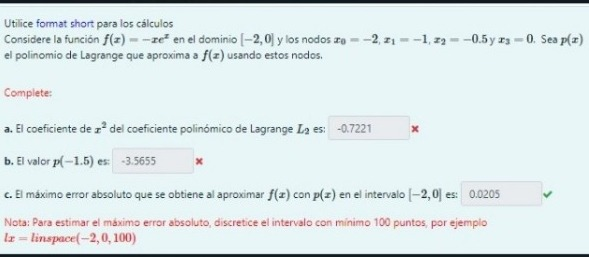

clear
syms f(x)


ans = 20.3041

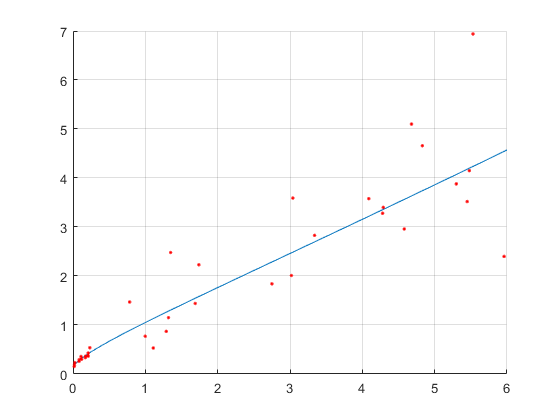

f(x) = -x*exp(x); % Definimos la función

X = [-2 -1 -.5 0]; % Definimos nodos en X
Y = eval(f(X)); % Definimos nodos en Y

help lagran

[C, L] = lagran(X, Y) % Evaluo Lagrange para hallar coeficientes
P = @(t) polyval(C, t); % Defino el polinomio
P(-1.5) % Evaluo el polinomio
f = matlabFunction(f); % Transformo la función

E = @(x) abs( P(x) - f(x) ); % Defino la función error

lx = linspace(-2, 0, 100); % Discretizo el espacio
max(E(lx)) % Hallo el máximo error

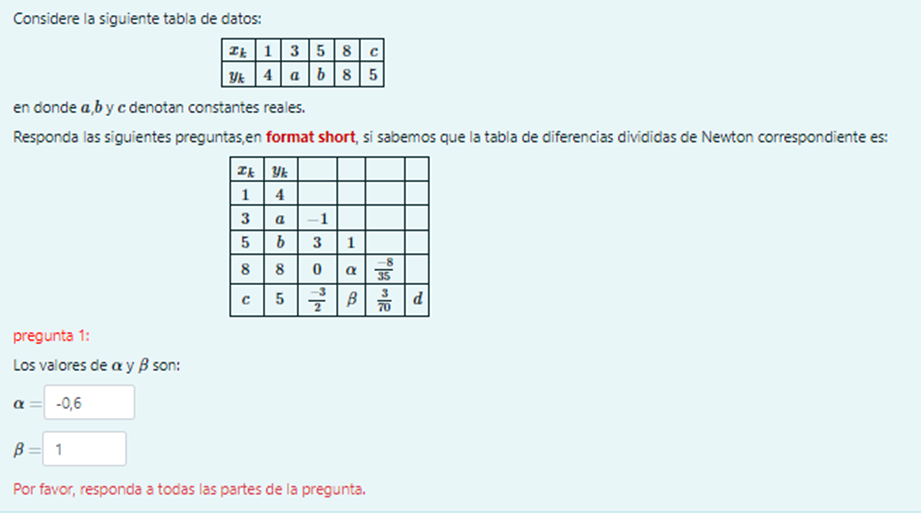

clear
syms beta alpha c 


  Entrada  - X es un vector que contiene una lista de las abscisas
           - Y es un vector que contiene una lista de las ordenadas
  Salida   - C es una matriz que contiene los coeficientes del
             polinomio interpolante de Lagrange
           - L es una matriz que contiene los coeficientes de los
             polinomios de Lagrange



alpha = (0 - 3) / (8 - 3) % Evaluo para hallar alpha

C =    -0.1632   -0.7221   -0.9268         0


L =    -0.3333   -0.5000   -0.1667         0
    2.0000    5.0000    2.0000         0
   -2.6667   -8.0000   -5.3333         0
    1.0000    3.5000    3.5000    1.0000


c = vpasolve( -3/2 == (5 - 8) / (c - 8) ) % Resuelvo el sistema para c
beta = (-3/2 - 0) / (c - 5) % Evaluo para hallar beta

ans = 0.3162

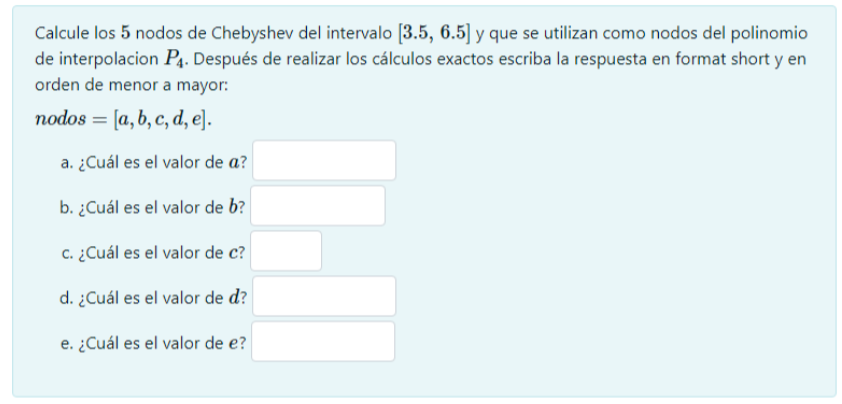

clear

help nodoschebyshev
f = @(x) 1; % Defino una función Dummy
X1 = nodoschebyshev(f, 4, 3.5, 6.5) % Hallo los nodos
g = @(x) sin(x); % Defino una función Dummy

ans = 0.0205

X2 = nodoschebyshev(g, 4, 3.5, 6.5) % Hallo los nodos
fliplr(X2) % Nodos organizados de menor a mayor

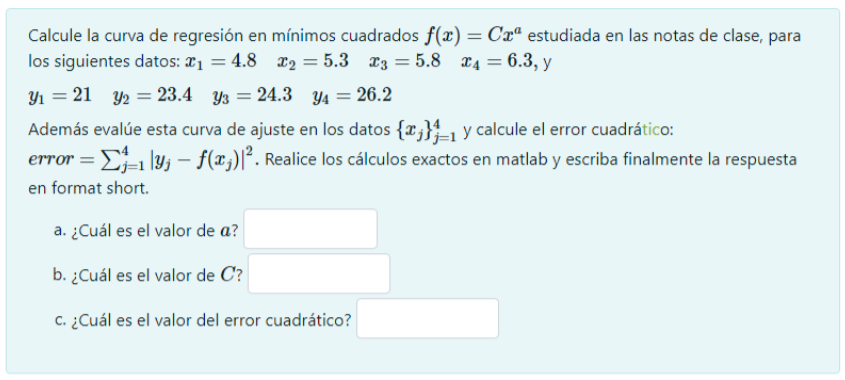

clear

X = [4.8 5.3 5.8 6.3]; % Defino los nodos en X
Y = [21 23.4 24.3 26.2]; % Defino los nodos en X

alpha = -0.6000

Veamos que la linealización asociada de la función: $\log \left(Y\right)=\log \left(C\right)+\;a\;\log \left(x\right)$

[a, c] = lsline(log(X), log(Y)); % Hallamos valores de linealización

$$c = 10.0$$

a, C = exp(c) % Hallamos coeficientes

$$beta = -0.3$$

f = @(x) C .* x .^ a; % Definimos el modelo

E = abs( Y - f(X) ); % Vector error
norm(E)^2 % Error cuadrado

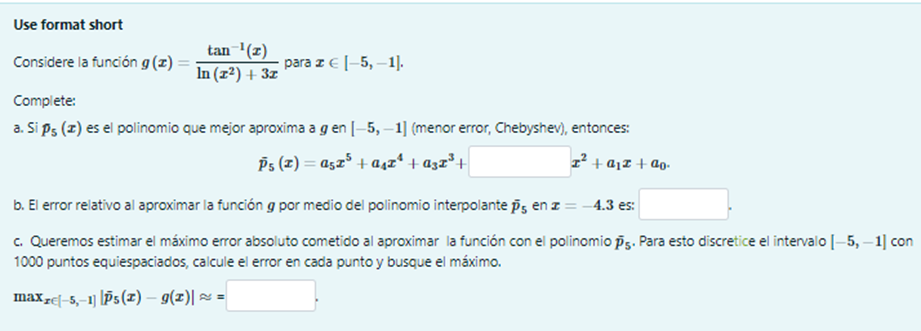

clear

  Entrada   - fun funcion creada con @
            - n es el grado del polinomio interpolante de Lagrange-Chebyshev
            - a es el extremo izquierdo
            - b es el extremo derecho
  Salida   
            - X contiene las abscisas
            - Y contiene las ordenadas



syms f(x)


X1 =     6.4266    5.8817    5.0000    4.1183    3.5734


f(x) = atan(x) / ( log(x^2) + 3*x ); % Defino la función
f = matlabFunction(f); % Convierto en matlab

X2 =     6.4266    5.8817    5.0000    4.1183    3.5734


ans =     3.5734    4.1183    5.0000    5.8817    6.4266


[~, X, Y] = cheby(f, 5, -5, -1); % Hallo nodos de Chebyshev
C = newpoly(X, Y); % Defino el polinomio

***Método 1: ****Verificando el vector coeficientes.*

disp(C); % Hallo el valor deseado siguiendo la forma estandard

***Método 2: ****Verificando el vector coeficientes.*

digits(4) % Cambio los digitos que muestra symbolic
vpa(poly2sym(C, x)) % Muestro el polinomio simbolico
P = @(x) polyval(C, x); % Defino el polinomio
Err = abs( P(-4.3) - f(-4.3) ); % Hallamos el error absoluto
rErr = Err / abs(f(-4.3)) % Hallamos el error relativo

a = 0.7765

C = 6.2753

Err = @(x) abs(f(x) - P(x)); % Definimos función error
lx = linspace(-5, -1, 1e3); % Realizamos un espacio equiespaciado
max(Err(lx)) % Hallamos valor máximo

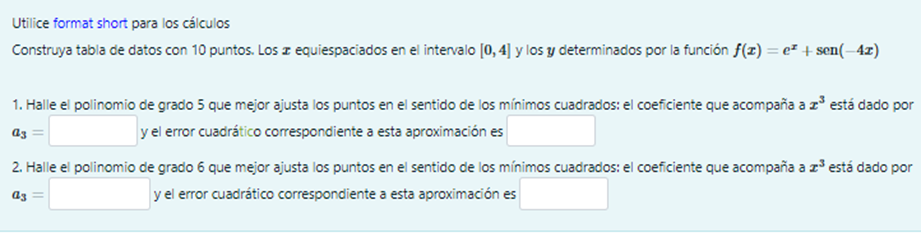

clear

ans = 0.3592

syms x

f = @(x) exp(x) + sin(-4 .* x); % Definimos la función

X = linspace(0, 4, 10); % Nodos equiespaciados
Y = f(X); % Evaluamos los nodos

C = lspoly(X, Y, 5) % Hallamos coeficientes
digits(6) % Configuramos los digitos
vpa( poly2sym(C, x) ) % Mostramos el polinomio

C =    -0.0011   -0.0186   -0.1261   -0.4053   -0.5570    0.0028


P = @(x) polyval(C, x); % Definimos el polinomio
Err = (Y - P(X)); % Hallamos vector error
norm(Err)^2 % Evaluamos error
C = lspoly(X, Y, 6) % Hallamos los coeficientes
vpa( poly2sym(C, x) ) % Mostramos el polinomio

$$ans = -0.001064\,x^{5}-0.0186\,x^{4}-0.1261\,x^{3}-0.4053\,x^{2}-0.557\,x+0.002787$$

P = @(x) polyval(C, x); % Definimos el polinomio
Err = (Y - P(X)); % Hallamos vector error
norm(Err)^2 % Evaluamos error

rErr = 0.0017

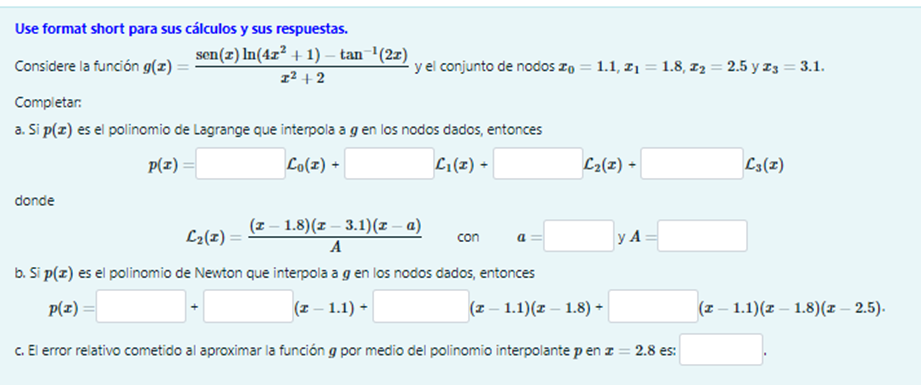

clear
syms f(x)


ans = 0.0013

f(x) = ( sin(x) * log(4*x^2 + 1) - atan(2*x) ) / (x^2 + 2); % Definimos la función
f = matlabFunction(f); % Convertimos la función

X = [1.1 1.8 2.5 3.1]; % Definimos los nodos de X
Y = f(X) % Definimos nodos de Y


$$L_2 \left(x\right)=\frac{\left(x-x_0 \right)\;\left(x-x_1 \right)\;\left(x-x_3 \right)}{\left(x_2 -x_0 \right)\left(x_2 -x_1 \right)\left(x_2 -x_3 \right)}$$


a = 1.1, A = (2.5 - 1.8)*(2.5 - 3.1)*(2.5 - 1.1) % Hallamos valores de a y A
[C, D] = newpoly(X, Y) % Conocemos los coeficientes y tabla de diferencias divididas
diag(D)' % Valores que acompañan la forma estandard de Newton
P = @(x) polyval(C, x); % Definimos el polinomio
Err = abs(P(2.8) - f(2.8)); % Hallamos el error absoluto
rErr = Err / abs(f(2.8)) % Hallamos el error relativo

C =     0.1057
   -0.5974
    1.6261
   -0.6788
    1.3518
    0.7774


$$ans = 0.105699\,x^{5}-0.597435\,x^{4}+1.62612\,x^{3}-0.678847\,x^{2}+1.35178\,x+0.777421$$

ans = 4.4079

C =     0.4475
   -5.2640
   23.5491
  -48.3545
   45.7705
  -13.7081
    1.0032


$$ans = 0.447475\,x^{6}-5.264\,x^{5}+23.5491\,x^{4}-48.3545\,x^{3}+45.7705\,x^{2}-13.7081\,x+1.00316$$

ans = 0.6709

Y =     0.1335    0.2419    0.0699   -0.1084


a = 1.1000

A = -0.5880

C =     0.1233   -0.9518    2.1223   -1.2135


D =     0.1335         0         0         0
    0.2419    0.1548         0         0
    0.0699   -0.2457   -0.2861         0
   -0.1084   -0.2971   -0.0395    0.1233


ans =     0.1335    0.1548   -0.2861    0.1233


rErr = 0.1490